# Vision: YOLO

In this notebook we will learn to adjust our gazebo scenes, collect images, label them, train our YOLO detector, and then leverage it. 

# 0. Connect to the Simulation

We will open up the UR simulation in gazebo.

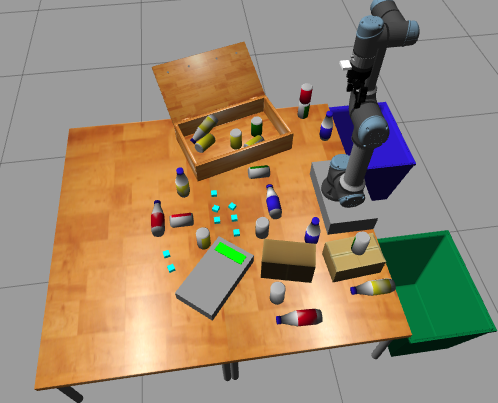

## 0.1 Run your Virtual Machine

To this end, you will need to run your virtual machine and start the armgazebo container. 

## 0.2 Run your Container

Remember to call run.bash from inside src/arm_gazebo/docker:

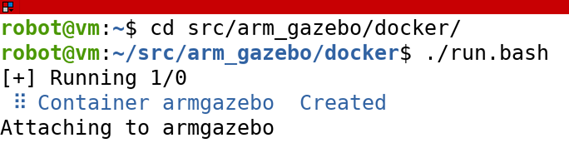

Also retrieve your hostname via command: hostname -I

## 0.3 Simplify your Scence

To start, let's simplify our scene, only keeping one object on our table. 

### 0.3.1 Changing the Staging File

- Open a terminator terminal and open tmux inside the armgazebo container:

            

- Change to the `src/armgazebo/config` folder:

- Open the ARM0.txt file using the text editor `gedit`: 

- Modify your file to only keep one object similar to the image below: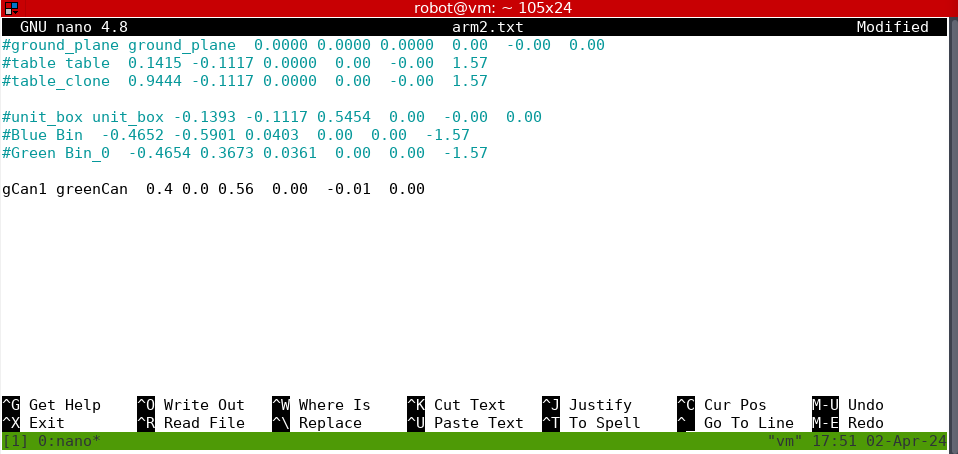

- Press Ctrl+o to save. At the bottom of the screen, Nano will prompt you to confirm the file name. Change the name to arm1.txt and press Enter. Confirm any other prompts.

### 0.3.2 Loading a new scene

Once we have this file, we can run a script to load gazebo with this staging file.

- Change directories from the config folder to the scripts folder: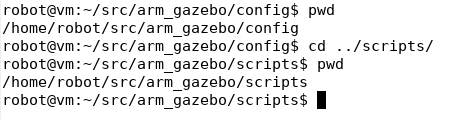

- If you call `ls`, you will see there are 3 executable scripts in this folder:

- You can call `reset_world.py` and pass it the path to your arm1.txt file to reset gazebo. Remember executables are run with a `./` and the path is one folder up and into config:

- After running it, you will see the terminal indicating objects are being deleted (you will see them disappear in gazebo) and finally **spawning** the objects in the new file: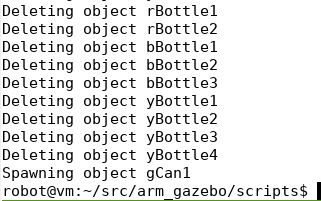  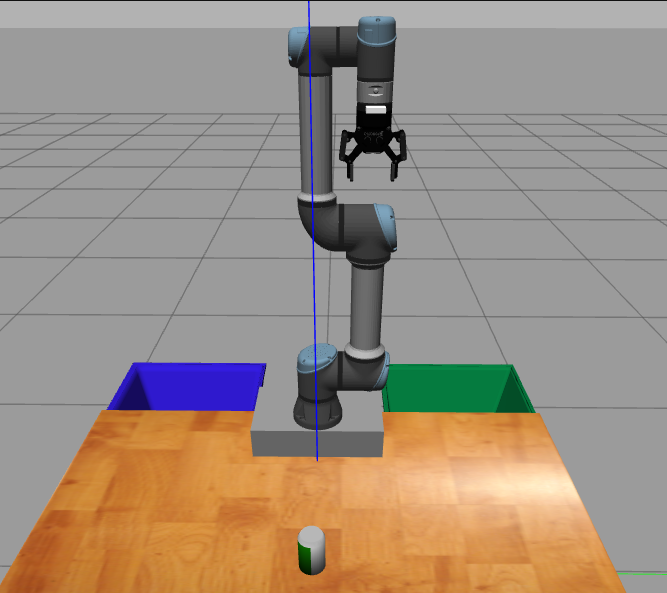

- We will start collecting a diverse set of images for one set at a time. Later, you will come back and change arm1.txt with {name,object} pairs like: 

            {`rCan1,redCan},{bBottle1,blueBottle},{pouch1,pouch}`

`      but keep the pose exactly the same.`

# 1. Data Collection

From our master ros_matlab code, change directory to the _vision/yolo folder.

The script `collect_yolo_data.m` selects a model and then calls `collect_obj_images. `The later will move the arm in concentric circles around the object taking pictures from different angles. There are 3 main parameters: 

- a rotation offset (determines the number of points to visit around the circle), 

- a linear offset (the distance from the center of the object at which to go around the circle), and 

- the number of iterations (the number of concentric circles at increasing offsets to execute).

#### Noise

Noise is injected into both the rotational and linear offsets to create different trajectories and as a result sets of images. This increased diversity should help with better training data.

#### **Caveats**

It is possible, that some images may not contain a can. That is, where the noise might have driven the arm a bit too far away from the can. These images will be labeled as null.

#### Image Names

The resulting images will be saved in a single image structure that will be saved in a data folder inside yolo. The name of the file uses the input model name to encode a name with the following pattern:

    color_objectType_yyyymmdd_HHMMSS.mat

## 1.1 Merging multiple Images

If you have multiple image structures, you can merge them with the `merge_img_structures.m` script/function. All your existing image structurse will be the input to the function, set the output as **yoloTrainingData **and save it also as 

Each time will be tasked to work with different objects. When you finish and obtain your final image structure, upload it to the following google drive link. We will use it to train the detector: [https://drive.google.com/drive/folders/1VQpBL9mi5HoMyaXcK60UaEWurd0Bp731?usp=sharing](https://drive.google.com/drive/folders/1VQpBL9mi5HoMyaXcK60UaEWurd0Bp731?usp=sharing) 

Note, that in this setup, we only have objects over the table. We should set up scenes where the objects are on top of boxes or other settings to get a more diverse set of images. 

# 2. Training the Yolo Network 

## 2.1 Labeling Images

All the images we have taken, need to be labeled using the [Image Labeler](docid:vision_ref.mw_96fe579b-b33c-4798-a463-6fdeee7cd214) app, creating the training dataset for the YOLO v2 detection model. 

***This sections is still in experimental mode and will require all of us to get it right.***

Using the Image Labeler app in MATLAB to train a YOLO (You Only Look Once) object detection algorithm involves several steps, including labeling your images, exporting the labeled data, and then structuring the data to fit the YOLO model's requirements. The ground truth vector you mentioned, a 7x1 vector for each labeled object, must be constructed from the labeled data. Let's break down the process into detailed steps:**Step 1: Labeling Images in the Image Labeler App**

- **Open the Image Labeler App**: In MATLAB, you can open the Image Labeler app by typing `imageLabeler` in the Command Window.

- **Load Your Dataset**: Import the images you want to label into the app. You can do this by choosing "Add Images" and selecting the images from your computer or workspace.

- **Define Label Categories**: Create label categories for your objects, such as cans, bottles, and pouches. Additionally, define bounding box labels for identifying the position of each object within the images.

- **Label Your Images**: Manually draw bounding boxes around each object in your images and assign them to the correct category (can, bottle, or pouch).

**Step 2: Exporting Labeled Data**

Once you've labeled your images, you can export the labeled data. The Image Labeler app allows you to export the data as a MATLAB table, which includes the bounding box coordinates and the object class labels.

- **Export the Data**: Use the export option to save your labeled data. The exported data typically includes variables for the image file names, bounding box coordinates, and class labels.

**Step 3: Structuring Data for YOLO**

The YOLO algorithm requires a specific format for the training data. You need to convert the exported table into a format where each object's label is represented by a 7x1 vector as you described:

- PcPc� (the class probability)

- BxBx� (x-center of bounding box)

- ByBy� (y-center of bounding box)

- BwBw� (width of bounding box)

- BhBh� (height of bounding box)

- class_1class_1, class_2class_2, class_3class_3 (binary indicators for cans, bottles, and pouches, respectively)

#### Actual Labeling 

Explore the labelling process through this blog:

[https://blogs.mathworks.com/student-lounge/2020/07/07/yolov2-object-detection-data-labelling-to-neural-networks-in-matlab/](https://blogs.mathworks.com/student-lounge/2020/07/07/yolov2-object-detection-data-labelling-to-neural-networks-in-matlab/) 

Note, assuming your exported data is in a table called `labeledData`, here is a conceptual MATLAB script to transform this data into the required format for each labeled object:

% Initialize a list to hold the ground truth vectors
groundTruths = {};

% Loop over each row in the labeled data
for i = 1:size(labeledData, 1)
    bbox = labeledData.bbox{i}; % Assuming 'bbox' is the bounding box column
    label = labeledData.label{i}; % Assuming 'label' is the class label column
    
    % Calculate the center (x, y), width, and height of the bounding box
    Bx = bbox(1) + bbox(3)/2;
    By = bbox(2) + bbox(4)/2;
    Bw = bbox(3);
    Bh = bbox(4);
    
    % Initialize class probabilities
    class_1 = 0; % cans
    class_2 = 0; % bottles
    class_3 = 0; % pouches
    
    % Update class probability based on the label
    if label == "can"
        class_1 = 1;
    elseif label == "bottle"
        class_2 = 1;
    elseif label == "pouch"
        class_3 = 1;
    end
    
    % Assuming Pc is 1 for all labeled objects
    Pc = 1;
    
    % Construct the ground truth vector
    gtVector = [Pc; Bx; By; Bw; Bh; class_1; class_2; class_3];
    
    % Append to the list
    groundTruths{end+1} = gtVector;
end


## 2.2 Training the Detector

Load the training data for the arm competition will follow the guidance of the matlab live notebook: 

TrainYOLOV2NetworkForVehicleDetectionExample.mlx

Edited for this problem:

Use your labelled images/anchors structure called `data`:

%data = load('yoloTrainingData.mat');
trainingData = data.armTrainingData; % Class table

Make sure you are in **./ros_matlab\code/_vision/yolo/data/merge**

dataDir = pwd;

trainingData.imageFilename = fullfile(dataDir,trainingData.imageFilename);

Randomly shuffle data for training.

rng(0);
shuffledIdx = randperm(height(trainingData)); % Get table height and permute entries
trainingData = trainingData(shuffledIdx,:);

#### Datastores

Datastores in MATLAB are a powerful and flexible way to manage large  collections of data, particularly when the data is too large to fit into memory all at once. A datastore is an object that enables you to read  and process data in chunks, making it possible to work efficiently with  big data. The concept is crucial for data analytics, machine learning,  and any application requiring the manipulation of large datasets. 

MATLAB datastores can handle a variety of data formats, including but  not limited to text files (CSV, TSV), images, spreadsheets, and binary  files. Specialized datastores are available for specific data types,  like `ImageDatastore` for image data, `TabularTextDatastore` for tabular text data, etc.

Typicall workflow is to:

- Create a datastore

- Read Data

- Process the data

Create an imageDatastore using the files from the table.

imds = imageDatastore(trainingData.imageFilename);

Create a boxLabelDatastore using the label columns from the table.

blds = boxLabelDatastore(trainingData(:,2:end));

Combine the datastores.

ds = combine(imds, blds);

#### Load a preinitialized YOLO v2 object detection network

Preinitialized networks allows us to do training faster as we do not need to train from scratch. Instead we are fine tuning the pre-trained model. 

net = load('yolov2VehicleDetector.mat');
lgraph = net.lgraph

Inspect the layers in the YOLO v2 network and their properties. You can also create the YOLO v2 network by following the steps given in [Create YOLO v2 Object Detection Network](docid:vision_ug#mw_4f6ea50f-8a93-4102-81a3-b2ba83bf7d58). 

lgraph.Layers

#### Network Hyperparameters

Configure the network training options.

hyperParams = trainingOptions('sgdm',...        % Set options for training the NN
          'InitialLearnRate',0.001,...
          'Verbose',true,...
          'MiniBatchSize',16,...
          'MaxEpochs',30,...
          'Shuffle','never',...
          'VerboseFrequency',30,...
          'CheckpointPath',tempdir);

#### Train the YOLO v2 network.

[`trainYOLOv2ObjectDetector`](docid:vision_ref.mw_0ff9d26a-9a79-4333-a1b1-ba03c8539ee3) trains the model. It can be called directly from above.

[detector,info] = trainYOLOv2ObjectDetector(ds,lgraph,hyperParams);

# 3. Online Inference

The trained model is deployed for online inference on the single image acquired by the on-board camera when the robot is in the home position. The [`detect`](docid:vision_ref.mw_9aaec1f6-72d8-4537-9ba6-79ac24fa5d0b) function returns the image position of the bounding boxes of the detected objects, along with their classes, that is then used to find the position of the center of the top part of the objects. Using a simple camera projection approach, assuming the height of the objects is known, the object position is projected into the world and finally used as reference position for picking the object. The class associated with the bounding boxes decides which bin to place the object. 

TODO...